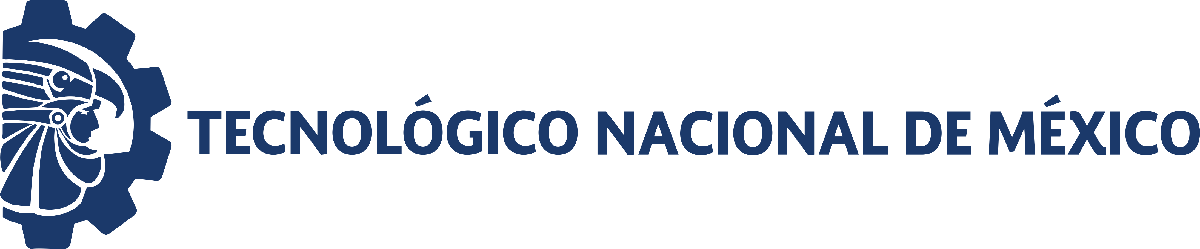                                 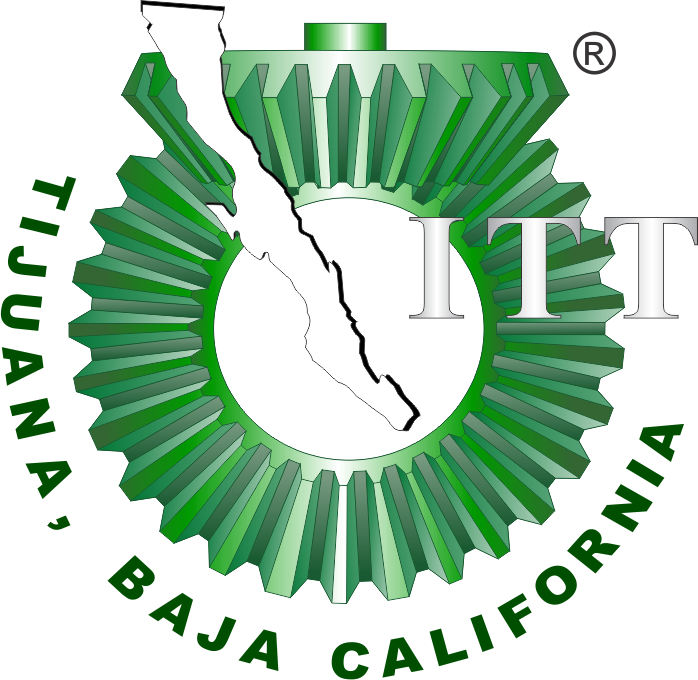

# Práctica 2: Lotka-Volterra predator-prey system 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

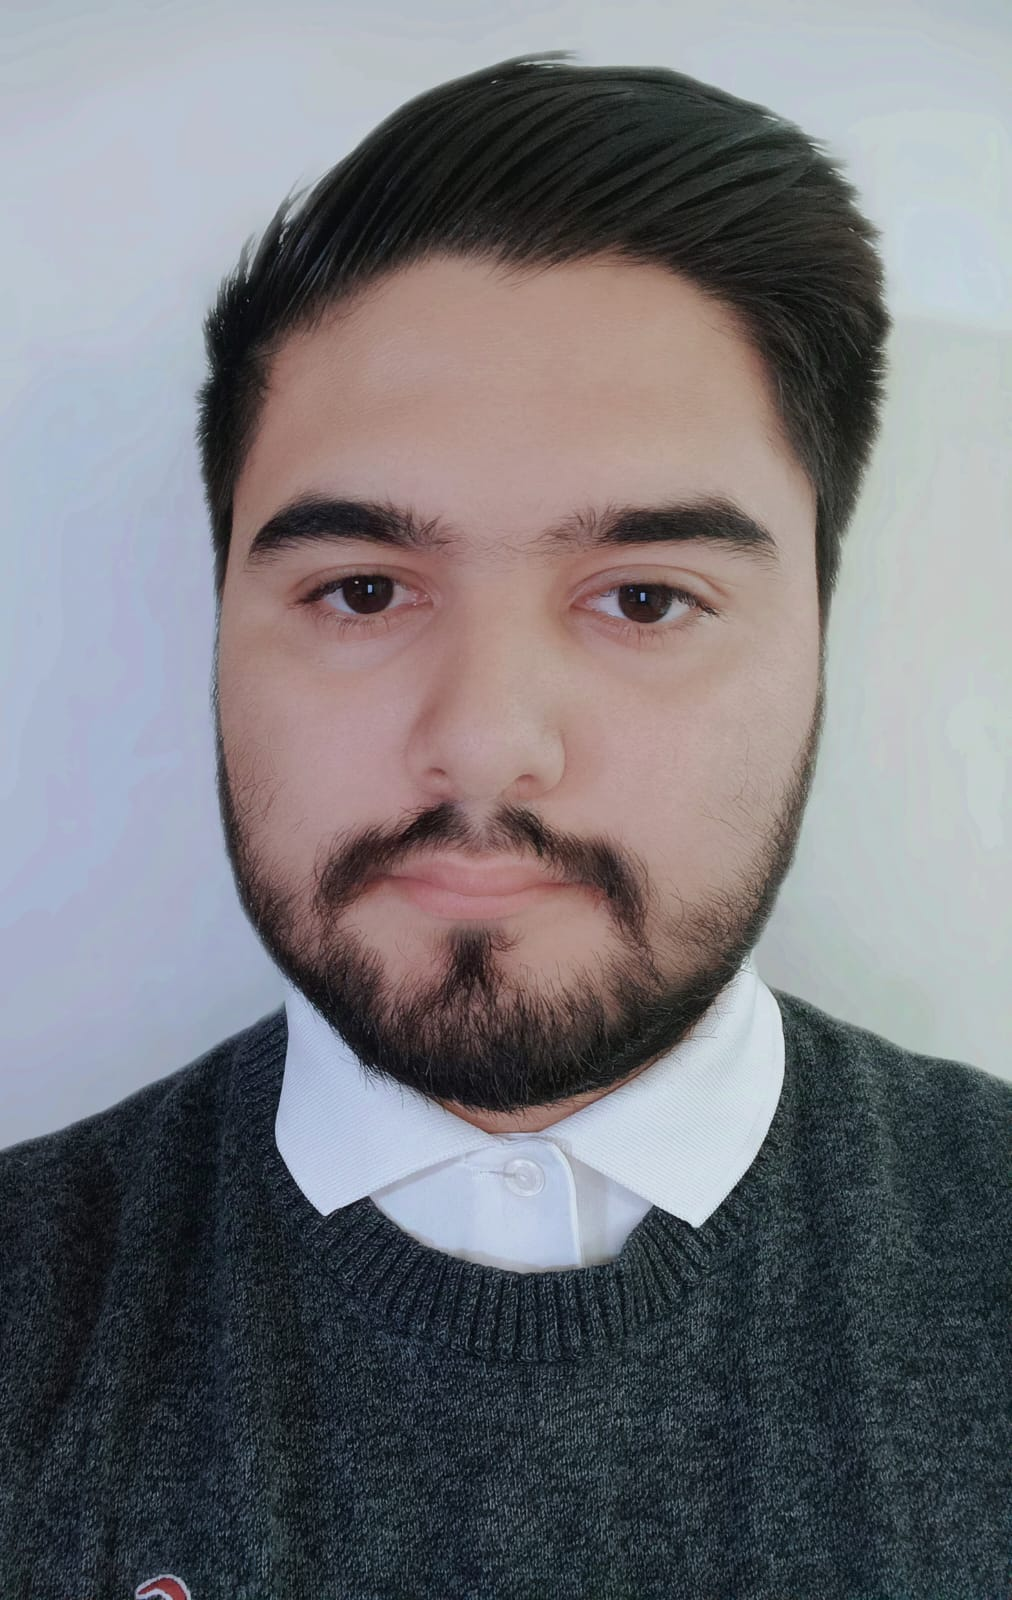

Nombre del alumno: Jose Sebastian Delgado Soto

Número de control: C20212281

Correo institucional: l20212281**@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Objetive**

Solve the Lotka-Volterra equations to study and illustrate their dynamics in time series and phase plane. The predator-prey system is formulated using the following two first-order ODEs:

$\dot{x}$=$\alpha x-\beta \textrm{xy}$

$\dot{y}$=$\delta \textrm{xy}-\gamma y$

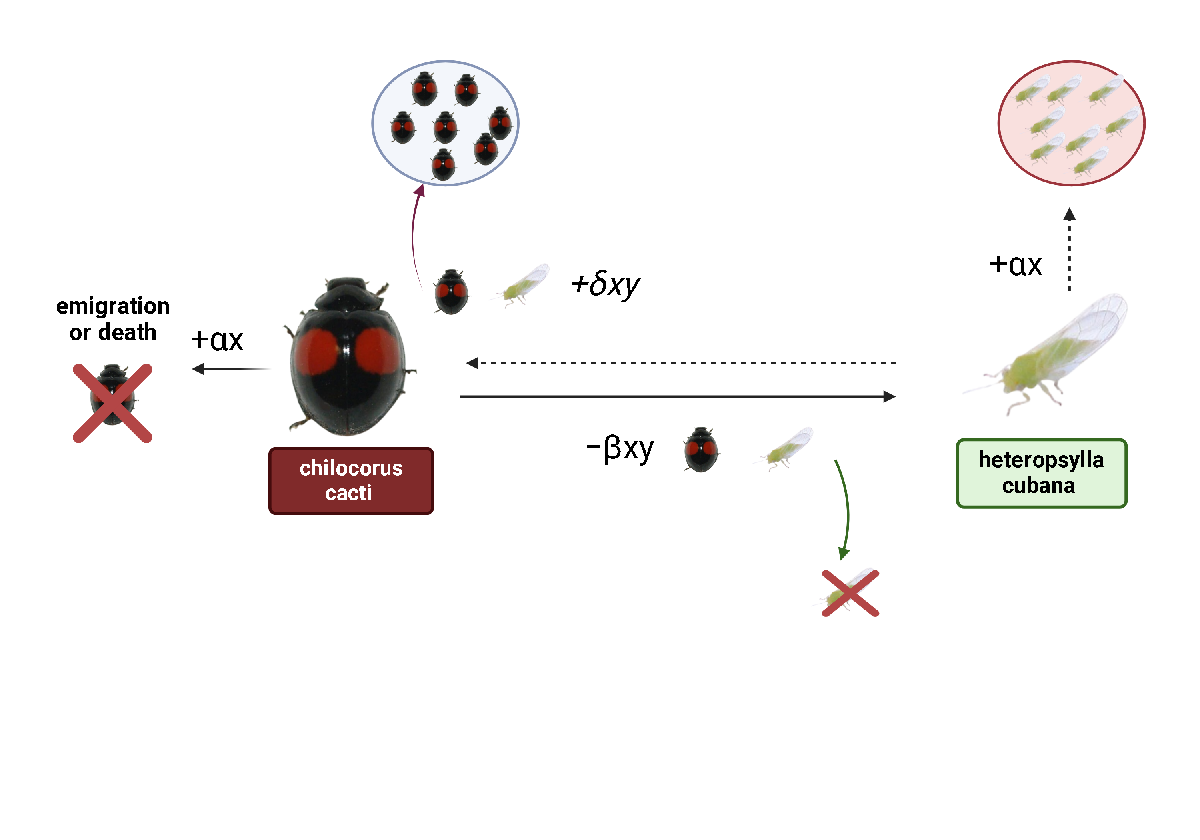

**Figure.** *Chilocorus cacti* [] encuentra a *Heteropsylla cubana* [], y estos encuentros resultan tanto en la depredación [retroalimentación negativa] de *Heteropsylla cubana* a una tasa β, como en la expansión [retroalimentación positiva] de *Chilocorus cacti* a una tasa δ. Además, *Chilocorus cacti* puede emigrar o morir [decaimiento exponencial] a una tasa dada por γ, y *Heteropsylla cubana* crece [crecimiento exponencial] a una tasa denotada por α.

## Simulation data

clc; clear; close all; warning('off','all')

## Parameters and initial condition

alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2; 
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75;  tend = 100;



## Solution by Euler's method

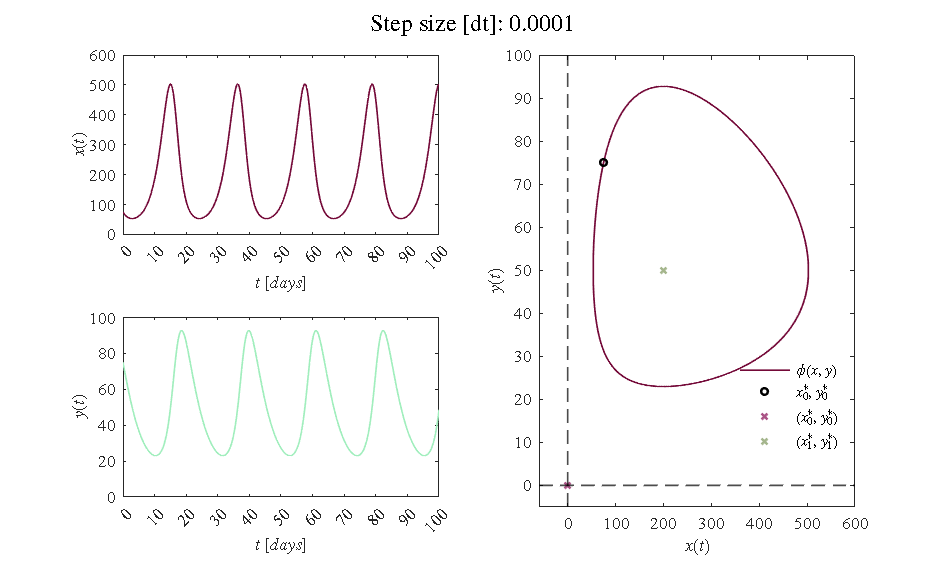

%%dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = 1E-4;
for i = 1:numel(dt)
     [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
     plotEDOs(t,x,y,P,dt(i))
     exportgraphics(gcf,['Lotka-Volterra Euler ', num2str(dt(i)),'.pdf']),
end

Solution heun metod

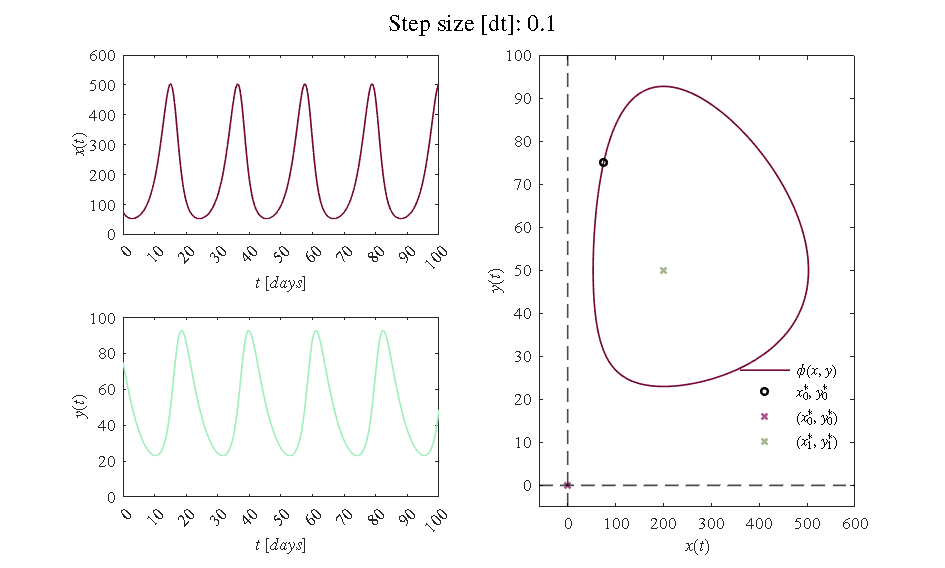


dt = 1E-1;
for i = 1:numel(dt)
     [t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
     plotEDOs(t,x,y,P,dt(i))
     exportgraphics(gcf,['Lotka-Volterra Heun ', num2str(dt(i)),'.pdf']),
end

## Simulink

file = 'system';
sim(file);
parameters.StopTime = '100'

parameters = struct with fields:
    StopTime: '100'


## Solution by ode15s [stiff solver]

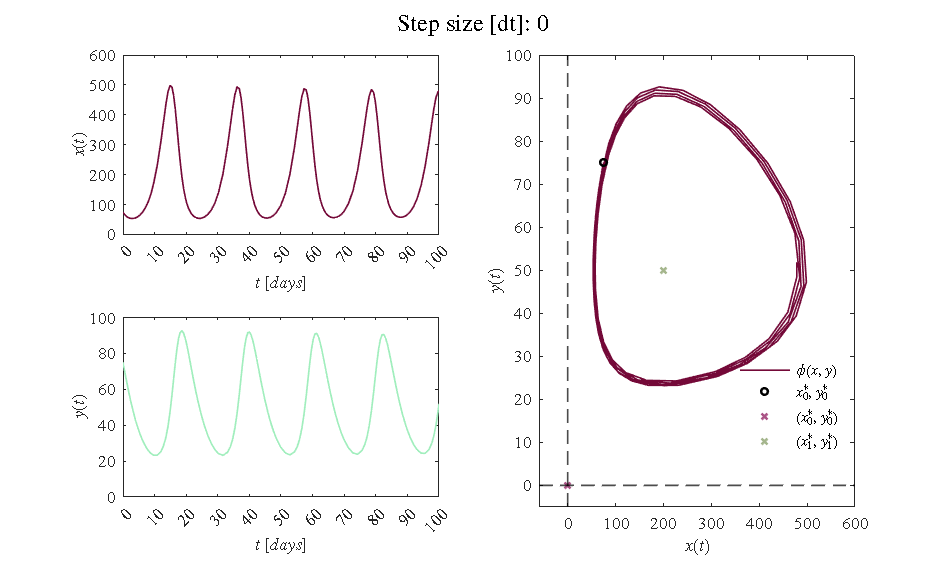

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
   exportgraphics(gcf, 'Lotka-Volterra ode15s.pdf', 'ContentType', 'vector')

## Solution by ode23s [stiff solver]

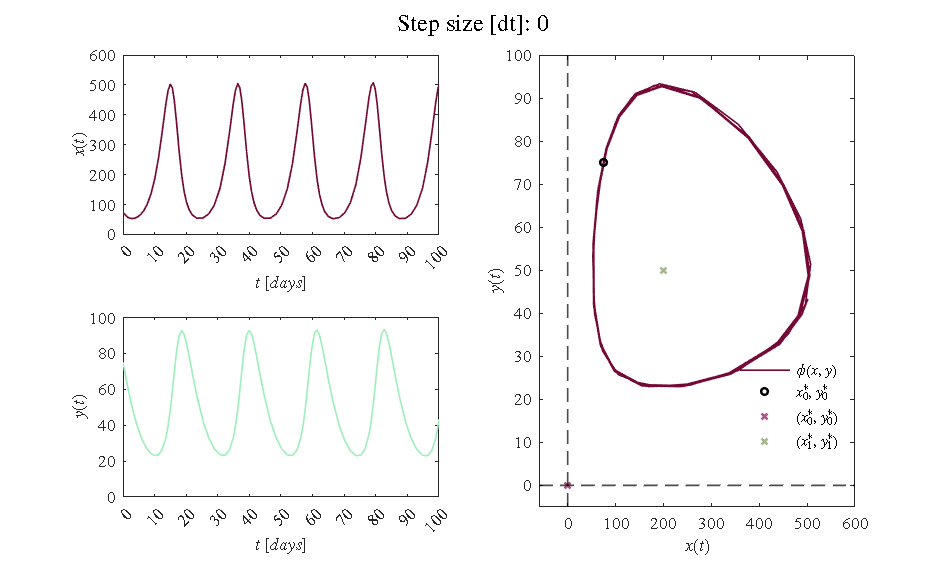

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
 exportgraphics(gcf, 'Lotka-Volterra ode23s.pdf', 'ContentType', 'vector')

## Solution by ode23t [stiff solver]

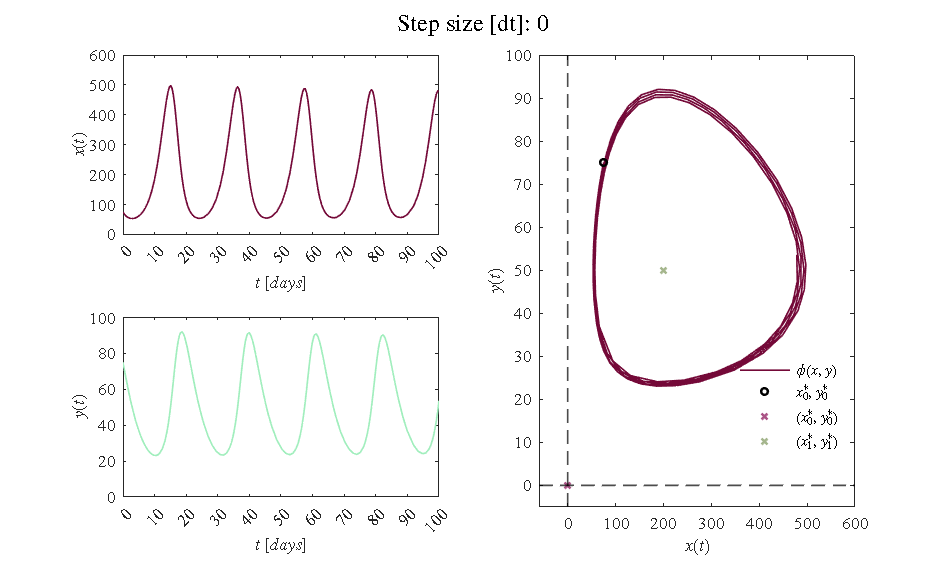

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
    exportgraphics(gcf, 'Lotka-Volterra ode23t.pdf', 'ContentType', 'vector')

## Solution by ode23tb [stiff solver]

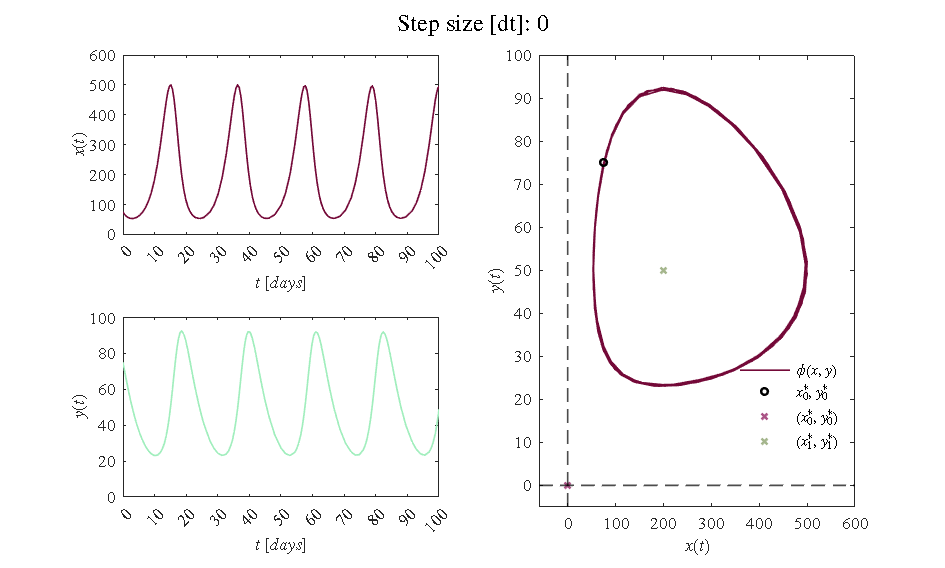

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
    exportgraphics(gcf, 'Lotka-Volterra ode23tb.pdf', 'ContentType', 'vector')

## Solution by ode45 [Nonstiff solver]

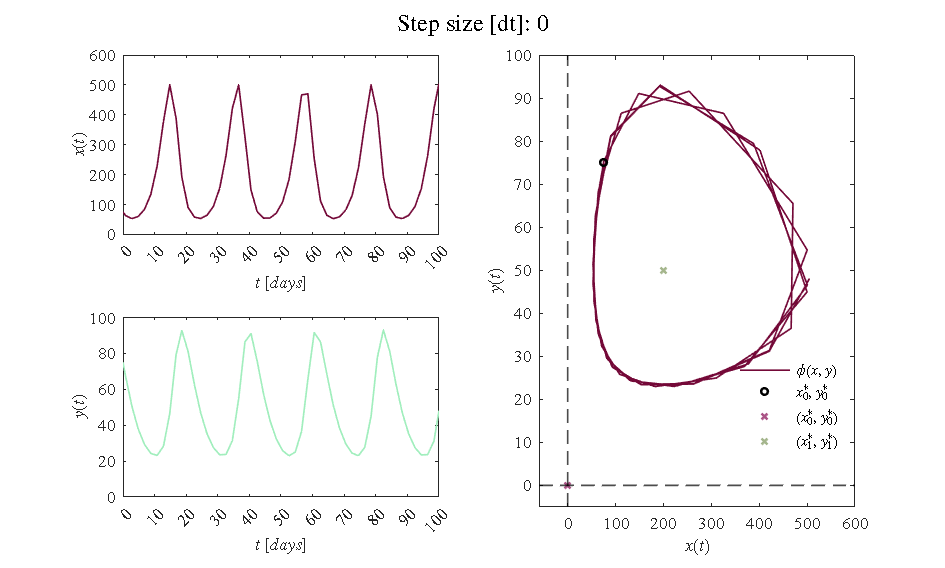

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
    exportgraphics(gcf, 'Lotka-Volterra ode45.pdf', 'ContentType', 'vector')

## Solution by ode23 [Nonstiff solver]

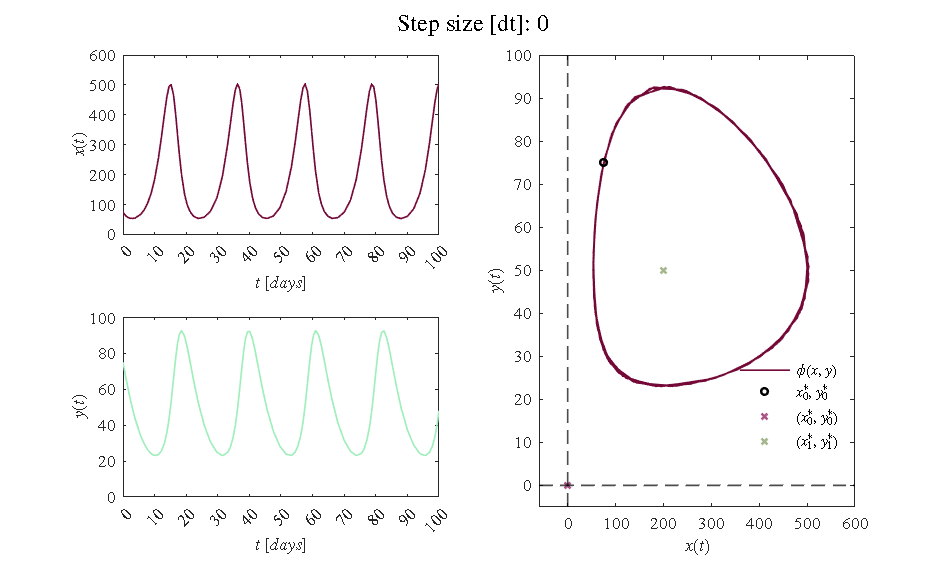

parameters.Solver = 'ode23';
s23 = sim(file,parameters);
plotEDOs(s23.t,s23.x,s23.y,P,0)
    exportgraphics(gcf, 'Lotka-Volterra ode23.pdf', 'ContentType', 'vector')

## Solution by ode123[Nonstiff solver]

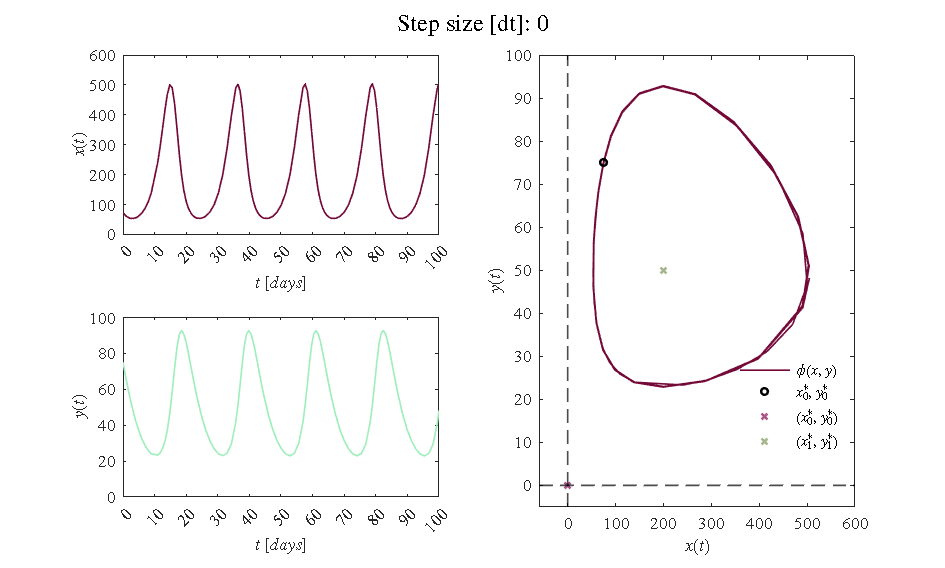

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf, 'Lotka-Volterra ode113.pdf', 'ContentType', 'vector')

Con base en las simulaciones numéricas, se observan las soluciones de x(t) y y(t) respecto al tiempo, en el ode23tb se puede observar una trayectoria mucho más estable y aproximada, es decir, más como una órbita periódica.Sin embargo el ode23 es mucho más estable y aproximado, mostrando una mejor trayectoria en su punto de equilibrio., también el tiempo de graficación fue mucho menor que los anteriores ode.

 Se concluye que el sistema de lotka-Volterra es nonstiff

Reference:

[1] P. A. Valle, Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México /Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2023. https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf?dl=0 

[2] A. Valinejad, A. Babaei, and Z. Zarei, “An Adaptive Time-Stepping Algorithm to Solve a Stochastic Lotka-Volterra Competition System with Time-Variable Delays,” *Control and Optimization in Applied Mathematics*, vol. 9, no. 2, pp. 187–199, Dec. 2024, doi: [https://doi.org/10.30473/coam.2024.67940.1237.](https://doi.org/10.30473/coam.2024.67940.1237.)

## Equilibrium points and jaconian matrix

clear; close all;  clc
syms x y alpha beta delta gamma
dx = alpha*x-beta*x*y;
dy = delta*x*y - gamma*y;

J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra System:'); disp(J)

Jacobian matrix of the Lotka-Volterra System:

$$\left(\begin{array}{cc} \alpha -\beta \,y & -\beta \,x\\ \delta \,y & \delta \,x-\gamma \end{array}\right)$$

dx = alpha*x-beta*x*y== 0;
dy = delta*x*y - gamma*y==0;

edos= solve([dx,dy],[x,y]);
fprintf(['The lotka-Volterra system has',num2str(length(edos.x)),'equilibrium points.']); 

The lotka-Volterra system has2equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
syms x0 y0 x1 y1
fprintf('Equilibrium points of the Lotka-Volterra systems');...
    disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1])

Equilibrium points of the Lotka-Volterra systems

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

clear aplha beta delta gamma
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;

disp('(x0,y0) = (0,0)');...
    disp(['(x1,y1)= (',num2str(gamma/delta),',',num2str(alpha/beta),')'])

(x0,y0) = (0,0)


(x1,y1)= (200,50)


## Local stability

clc; clear; close all; warning('off','all')
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
syms x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0;x1]; y = [y0;y1];
var = {'(x0,y0)';'(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
               xe     ye
               ___    __

    (x0,y0)      0     0
    (x1,y1)    200    50



L = zeros(length(x),length(y));
for i = 1: length(x)
    J= [alpha - beta*y(i),       -beta*x(i);
                delta*y(i),delta*x(i)-gamma]

    L(i,:) = eig(J);


end

J =     0.5000         0
         0   -0.2000


J =          0   -2.0000
    0.0500         0



L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp (Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                    L1               L2     
               _____________    ____________

    (x0,y0)    -0.2+0i          0.5+0i      
    (x1,y1)       0+0.31623i      0-0.31623i



## Equilibrium Point

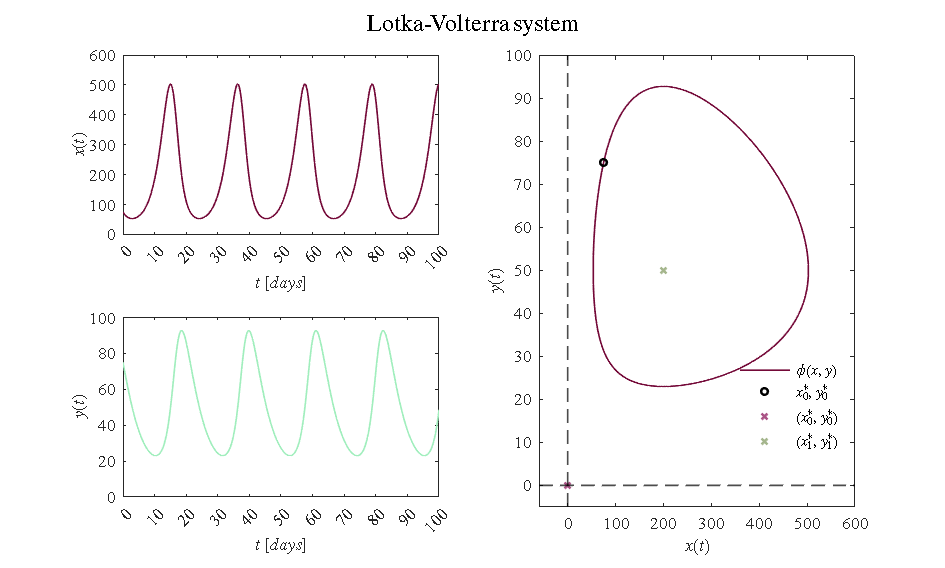

alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;
dt = 1E-4;
[t,x,y] = sys_Heun(x0,y0,dt,tend,P);
plotEDOs(t,x,y,P,dt); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Lotka-Volterra Equilibria.pdf','ContentType','vector')

## Data fitting

clc; clear; close all

##  Raw data

sys = readmatrix('data.xlsx');
to = round(sys(:,1));
xo = sys(:,2); yo = sys(:,3); 
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];

T = array2table([to,xo,yo],'VariableNames',{'t[min]','x','y'}); %disp(T);

## Smooth data

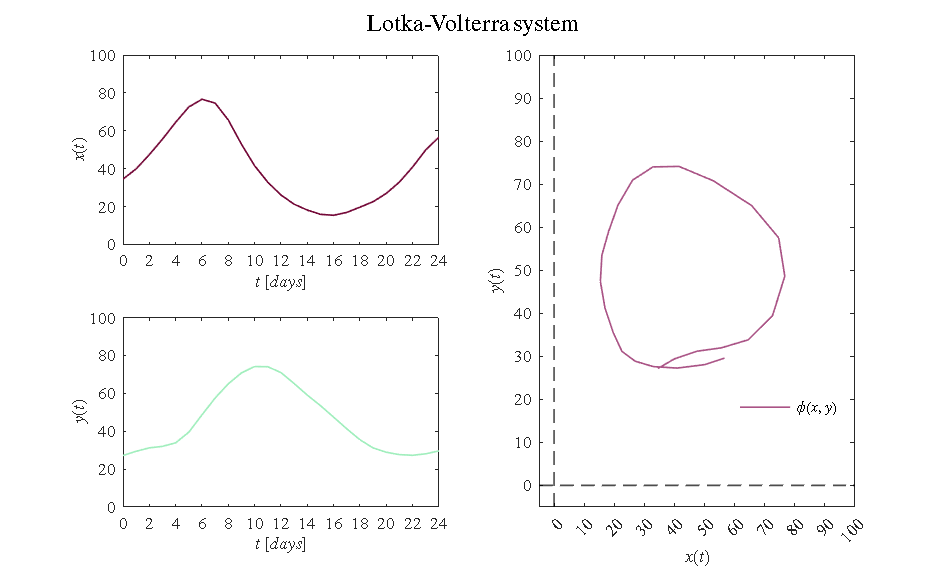

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsxd(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'data fitting Lotka-Volterra.pdf','ContentType','vector')

## Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);


Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.05
t-Student value: 2.0129
Adjusted R-squared: 0.99028
Corrected AIC (n/pars < 40): 206.6039

    Parameters    Estimate         SE           MoE                 CI95               pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.40857     0.0077876      0.015676      0.39289      0.42425    1.0859e-42
      beta        0.0086529    0.00019567    0.00039387     0.008259    0.0090468    2.4277e-39
      delta       0.0055233    0.00012323    0.00024805    0.0052753    0.0057714    1.3238e-39
      gamma         0.22612     0.0051865       0.01044      0.21568      0.23656    4.5981e-39



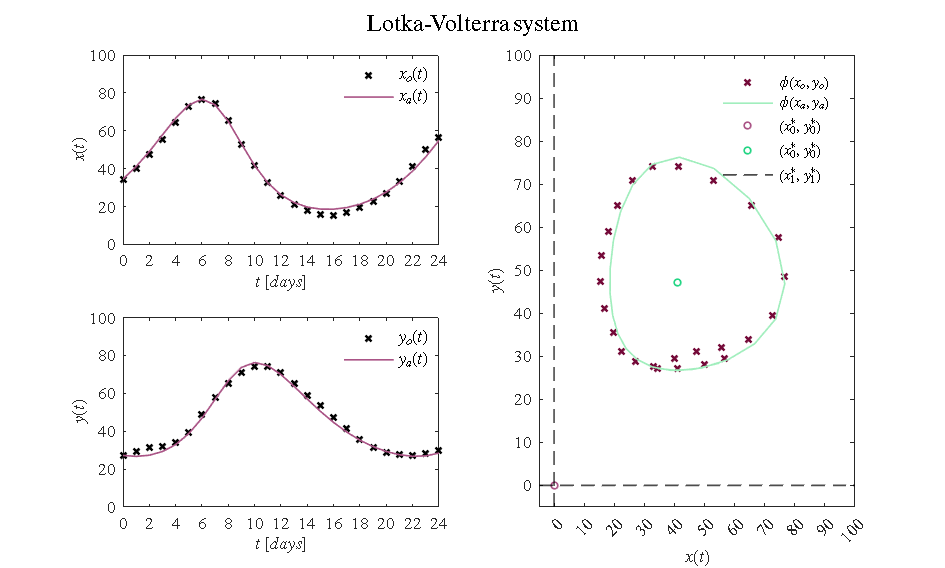


fa = mdl.Fitted;
fx= reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));


plotResults(to,[xo,xa],[yo,ya],P); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Lotka-Volterra(fitted).pdf','ContentType','vector')

## system 

clc; clear; close all
sys = readmatrix('data2.xlsx');
to = round(sys(:,1));
xo = sys(:,2); yo = sys(:,3); 
alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];

T = array2table([to,xo,yo],'VariableNames',{'t[min]','x','y'}); %disp(T);

    t[min]      x         y   
    ______    ______    ______

       1      51.074    42.996
       2      63.738    31.687
       3      84.172    30.992
       4      104.25    41.111
       5      95.517    69.385
       6      71.012    76.627
       7      56.068    67.698
       8      50.328     53.81
       9      54.985    36.647
      10      69.921    30.496
      11      91.789    32.976
      12      106.37    54.802



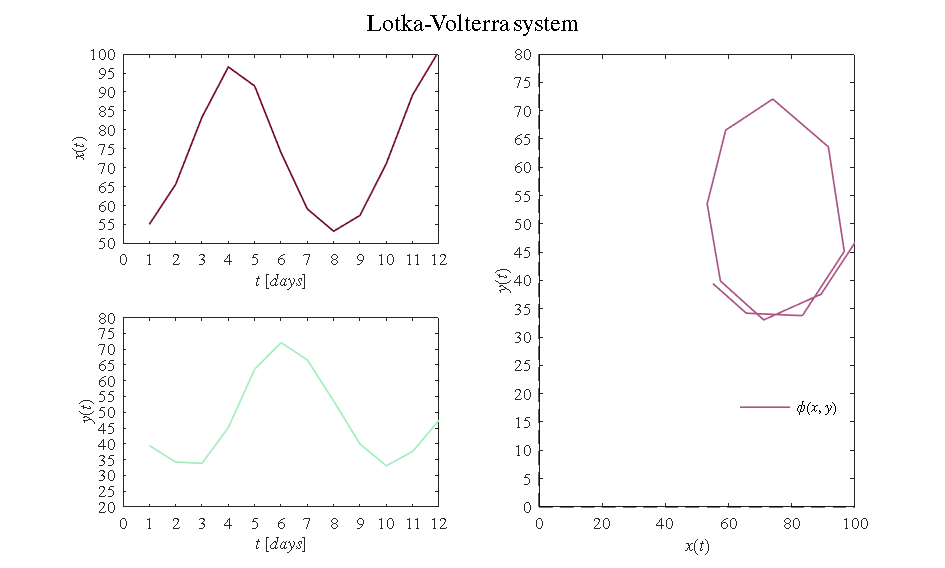


xo = smoothdata(xo,'gaussian',4);
yo = smoothdata(yo,'gaussian',4);
plotEDOssis(to,xo,yo,P,0); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'sistem Lotka-Volterra.pdf','ContentType','vector')


P0 = [0.4, 0.01, 0.09, 1.1]; % Valores cercanos a la tabla
   % Ajuste inicial
mdl = variant(to,xo,yo,P0);


Sample size (n): 12
Parameters to be estimated (pars): 4
Degrees of freedom: 20
Significance level (alpha): 0.05
t-Student value: 2.086
Adjusted R-squared: 0.92439
Corrected AIC (n/pars < 40): 157.2817

    Parameters    Estimate       SE          MoE                CI95               pvalue  
    __________    ________    ________    _________    ______________________    __________

      alpha        0.51212    0.060608      0.12643      0.38569      0.63854    4.9574e-08
      beta        0.010764    0.001349     0.002814    0.0079496     0.013578    1.2145e-07
      delta       0.014726    0.002255    0.0047039     0.010022      0.01943    2.3022e-06
      gamma         1.0808     0.15997      0.33368      0.74714       1.4145    1.4272e-06



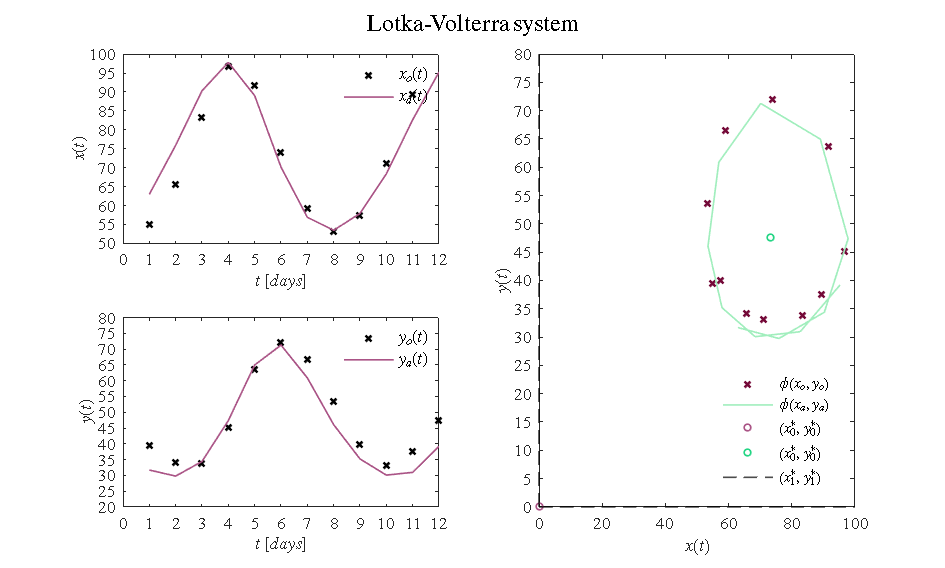


fa = mdl.Fitted;
fx= reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults2(to,[xo,xa],[yo,ya],P); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf,'Lotka-Volterra(fitted).pdf','ContentType','vector')

## ‌

## Functions

### Euler'Methods

function [t, x, y] = sys_Euler(x0, y0, dt, tend, P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend / dt);
    t = (0:dt:tend)';
    
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i) + dt * (alpha * x(i) - beta * x(i) * y(i));
        y(i+1) = y(i) + dt * (delta * x(i) * y(i) - gamma * y(i));
    end
end



### heun 's method

function [t, x, y] = sys_Heun(x0, y0, dt, tend, P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend / dt);
    t = (0:dt:tend)';
    
    x = zeros(length(t), 1); x(1) = x0;
    y = zeros(length(t), 1); y(1) = y0;

    for i =1: n
        [fx,fy] = f(x(i),y(i));

        xn = x(i) +fx*dt;
        yn = y(i) +fy*dt;
        [fxn,fyn] = f(xn,yn);

        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;


    end

    function [dx,dy] = f(x,y)

        dx = alpha*x -beta*x*y;
        dy = delta*x*y -gamma*y;
    end

end

## Solutions and trajectories

function plotEDOs(t,x,y,P,dt)
set(figure(), 'Color','w')
c1=[116, 9, 56]/255;  
c2=[161, 238, 189]/255;  
c3=[170, 84, 134]/255; 
set(gcf, 'Units','Centimeters', 'Position', [2,2,20,12])
alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

subplot(2,2,1)
set(gca,'FontName', 'Times New Roman'); fontsize(10,'points')
hold on; box on; grid off;
plot(t,x,'-','LineWidth',1, 'Color',c1)
xlabel('$t$ $[days]$', 'Interpreter','latex')
ylabel('$x(t)$', 'Interpreter','latex')
xlim([0 100]); xticks(0:10:100)
ylim([0 600]); yticks(0:100:600)

subplot(2,2,3)
set(gca,'FontName', 'Times New Roman'); fontsize(10,'points')
hold on; box on; grid off;
plot(t,y,'-','LineWidth',1, 'Color',c2)
xlabel('$t$ $[days]$', 'Interpreter','latex')
ylabel('$y(t)$', 'Interpreter','latex')
xlim([0 100]); xticks(0:10:100)
ylim([0 100]); yticks(0:20:100)

   subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c1)
    plot(x(1),y(1),'o','MarkerSize',4,'LineWidth',1.5,'Color',[0, 0, 0])
    plot(0,0,'x','MarkerSize',5,'LineWidth',1.5,'Color',c3)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',1.5,'Color',[165, 182, 141]/255);
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$','$x^*_0,y^*_0$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    % L = legend('$\phi(x,y)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')

ttl = ['Step size [dt]:  ', num2str(dt)];
sgtitle(ttl, 'Interpreter', 'Latex')
end





$$\dot{x}$$


## Function Fit

function plotEDOsxd(t,x,y,P,dt)
c1=[116, 9, 56]/255;  
c2=[161, 238, 189]/255;  
c3=[170, 84, 134]/255; 
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
    
    if dt == 0
        ttl = 'Lotka-Volterra System';
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
    end
end

function plotResults(t,x,y,P)
c1=[116, 9, 56]/255;  
c2=[161, 238, 189]/255;  
c3=[170, 84, 134]/255; 
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0, 0, 0])
    plot(t,x(:,2),'-','LineWidth',1,'Color',c3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0, 0, 0])
    plot(t,y(:,2),'-','LineWidth',1,'Color',c3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

 subplot(2,2,[2,4])
set(gca,'FontName','Times New Roman'); fontsize(10,'points')
hold on; box on; grid off;     

plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1) 
plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c2) 
plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',c3) 
plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',[35 213 132]/255)

xlabel('$x(t)$','Interpreter','latex')
ylabel('$y(t)$','Interpreter','latex')

xlim([-5 100]); xticks(0:10:100)
ylim([-5 100]); yticks(0:10:100)

xline(0,'--','LineWidth',1,'Color','k')
yline(0,'--','LineWidth',1,'Color','k')

L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
set(L,'Interpreter','latex','Location','Best','Box','Off')

    
end


## Function Sis

function plotEDOssis(t,x,y,P,dt)
c1=[116, 9, 56]/255;  
c2=[161, 238, 189]/255;  
c3=[170, 84, 134]/255; 
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    
   xlim([0 12]); xticks(0:1:12)
    ylim([50 100]); yticks(50:5:100)
    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 12]); xticks(0:1:12)
    ylim([20 80]); yticks(20:5:80)

    subplot(2,2,[2,4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:20:100)
    ylim([0 80]); yticks(0: 5:80)

    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    L = legend('$\phi(x,y)$');
    set(L,'Interpreter','Latex','Location','none','Position',[0.778,0.263,0.115,0.041],'Box','Off')
    
    if dt == 0
        ttl = 'Lotka-Volterra System';
        sgtitle(ttl,'Interpreter','Latex');
    else
        ttl = ['Step size: ',num2str(dt)];
        sgtitle(ttl,'Interpreter','Latex');
    end
end

function plotResults2(t,x,y,P)
c1=[116, 9, 56]/255;  
c2=[161, 238, 189]/255;  
c3=[170, 84, 134]/255; 
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0, 0, 0])
    plot(t,x(:,2),'-','LineWidth',1,'Color',c3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    xlim([0 12]); xticks(0:1:12)
    ylim([50 100]); yticks(50:5:100)


    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',[0, 0, 0])
    plot(t,y(:,2),'-','LineWidth',1,'Color',c3)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
     xlim([0 12]); xticks(0:1:12)
    ylim([20 80]); yticks(20:5:80)


 subplot(2,2,[2,4])
set(gca,'FontName','Times New Roman'); fontsize(10,'points')
hold on; box on; grid off;     

plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1) 
plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c2) 
plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',c3) 
plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',[35 213 132]/255)

xlabel('$x(t)$','Interpreter','latex')
ylabel('$y(t)$','Interpreter','latex')

xlim([0 100]); xticks(0:20:100)
    ylim([0 80]); yticks(0: 5:80)

xline(0,'--','LineWidth',1,'Color','k')
yline(0,'--','LineWidth',1,'Color','k')

L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
set(L,'Interpreter','latex','Location','Best','Box','Off')

    
end


## Nonlinear regression algorithm

function mdl = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i)); % Evalúa la función f(x,y) en el valor actual x(i) y(i).
            xn = x(i) + fx*dt; % Método de Euler para obtener un valor provisional xn
            yn = y(i) + fy*dt; % Método de Euler para obtener un valor provisional yn
            [fxn,fyn] = f(xn,yn); % Evalúa f(x,y) en el valor actual xn yn
            x(i+1) = x(i) + (fx + fxn)*dt/2; % Método de Heun para x
            y(i+1) = y(i) + (fy + fyn) * dt/2; % Método de Heun para y
        end

        function [dx,dy] = f(x,y) % Función llamada f, que toma un argumento de entrada x1 y devuelve un valor de salida dx1.
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end

        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)
end